Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 4 -- Random Variables

%{
    This will be a script that will solve the problems in Assignment 4.
    This will be used to explore the behavior of random variables and what
    happens when we take an expected value of a random variable.

    Sam Kramer
    Feb 1st, 2023
%}

% --Script setup
    clear; clc; close all; format compact;

### Problem Statement

    We discussed in class how expected value functions operate to separate the random content from deterministic variables. This assignment is an exercise to validate the discussion in class.

Let X and Y be true values related by Y=aX 

x is measured data

y is measured date

ex= error in x and is related to x by x=X+ex

ey = error in y and is related to y by y=Y+ey

Create two vectors of for ex and ey , Create another vector X and calculate Y by assuming a value for a. Combine the vectors to obtain x and y as we formed in class. 

        1. E[xy]=[(X+ex )(Y=ey )] expand this out into the individual terms and validate that each term performs as in class. Use vector lengths of 10, 100, 1000.

        2. Do the same for E[xx] and E[yy]  ie show E[xx] =E[XX] +E[ex ex ]  etc. 

Be sure random content is (N,0) you can use (U,0) well.

### Problem Calculations

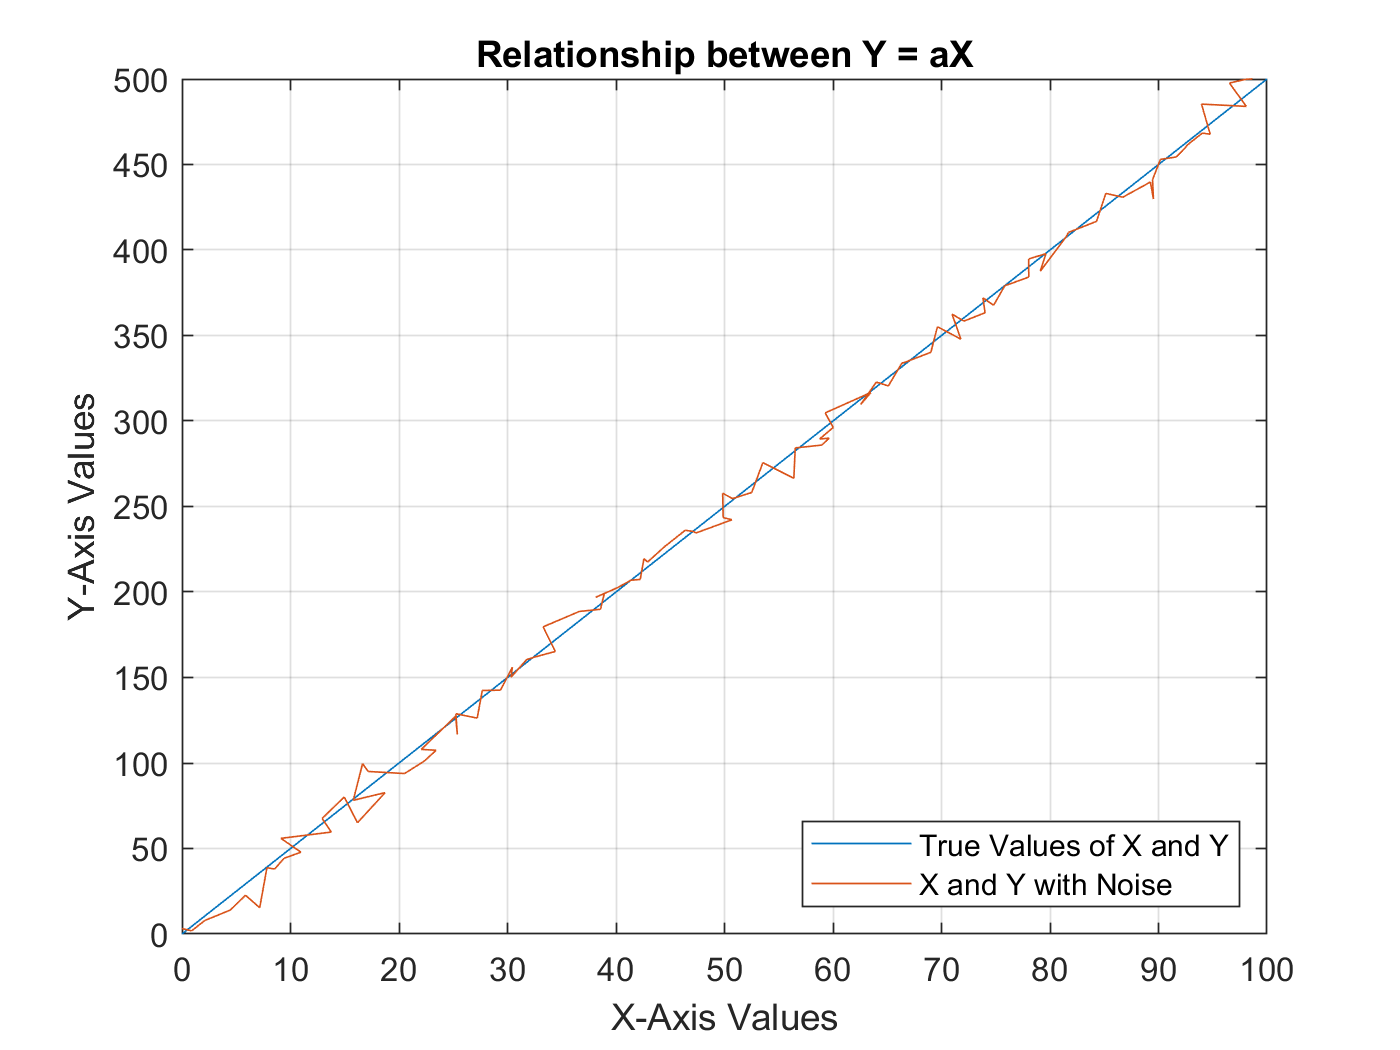

% --Parameters
    a = 5;                              % Relationship between X and Y
    X = 0:100;                          % Range of X values for this problem
    Y = a.*X;                           % Creating Y Values for this problem
    N = [10, 100, 1000];                % The lengths E[xy] calculations
    solutions = zeros(12,length(N));    % Solution vectors
    sums = zeros(4,length(N));          % Summation solution vector
    Sol = zeros(1,length(N)); 
    
% --Plot relation between Y and X
    figure(1)
    plot(X,Y)
        hold on
    
% --Add random content to X and Y
    ex = randn(1,length(X));            % Random decimal noise to X
    x = X + ex;                         % X with random noise
    ey = randn(1,length(Y))*5;          % Random noise to Y
    y = Y + ey;                         % Y with random noise
    
% --Plot relation between x and y
    plot(x,y)
        xlim([0 100])
        ylim([0 500])
        grid on 
        hold on
        xlabel('X-Axis Values')
        ylabel('Y-Axis Values')
        title('Relationship between Y = aX')
        lgd = legend('True Values of X and Y', 'X and Y with Noise');
            lgd.Location = 'southeast';

            
% --Calculate the expected value for the proplems
    
    for i = 1:length(N)
        
        % --Problem setup
            X = linspace(0,10,N(i));
            Y = a*X; 
            ex = randn(1, length(X));
            ey = randn(1, length(Y))*5;
            x = X + ex;
            y = Y + ey; 
            
        % --Calculating expected value and expanding out E[xy] to 
            % E[xy], E[x*ey], E[ex*y], E[exey]
            Exy = mean(x.*y);           % E[xy]
            Exey = mean(x.*ey);         % E[x*ey]
            Eexy = mean(ex.*y);         % E[ex*y]
            Eexey = mean(ex.*ey);       % E[exey]
            
            xy = Exy + Exey + Eexy + Eexey;     % Sommation of all values
            
            % --Store data
                solutions(1,i) = Exy;
                solutions(2,i) = Exey;
                solutions(3,i) = Eexy;
                solutions(4,i) = Eexey; 
                
                Sol(1,i) = xy;
                
        % --Calculating the expected value of the expanded E[xx]
            % E[xx], E[x*ex], E[ex*x], E[ex*ex]
            Exx = mean(x.*x);           % E[xx]
            Exex = mean(x.*ex);         % E[x*ex]
            Eexx = mean(ex.*x);         % E[ex*x]
            Eexex = mean(ex.*ex);       % E[ex*ex]
            EXX = mean(X.*X);           % E[XX]
            
            sumXX = EXX + Eexex;        % Sum of the data
            
            % --Store data
                solutions(5,i) = Exx;
                solutions(6,i) = Exex;
                solutions(7,i) = Eexx;
                solutions(8,i) = Eexex;
                
                sums(1,i) = Exx;          % Stores the sums of the data
                sums(2,i) = sumXX;
                
        % --Calculating the expected value of the expanded E[yy]
            Eyy = mean(y.*y);           % E[yy]
            Eyey = mean(y.*ey);         % E[y*ey]
            Eeyy = mean(ey.*y);         % E[ey*y]
            Eeyey = mean(ey.*ey);       % E[ey*ey]
            EYY = mean(Y.*Y);           % E[YY]
          
            sumYY = EYY + Eeyey;        % Esimation of E[yy]
          
            varYY = y.*y;               % calculation of y*y
          
            % --Store data
                solutions(9,i) = Eyy;
                solutions(10,i) = Eyey;
                solutions(11,i) = Eeyy;
                solutions(12,i) = Eeyey;
              
                sums(3,i) = Eyy;          % Stores the sums of the data
                sums(4,i) = sumYY;
    end

### Analysis of Data    

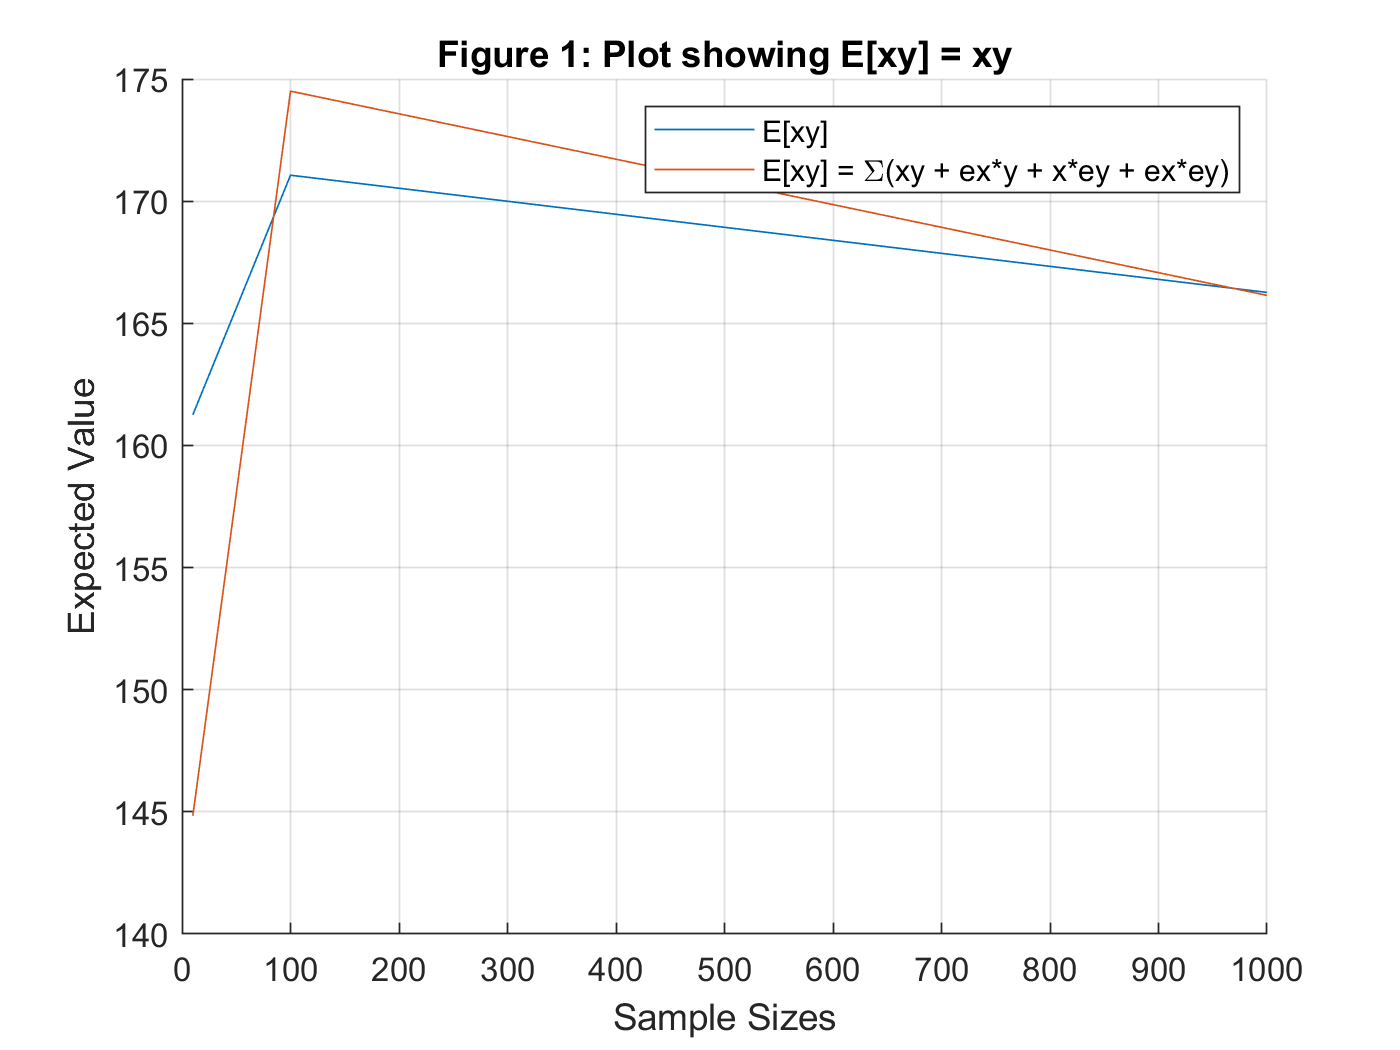

% --Plot E[xy]
    figure(2)
    hold on
    plot(N,solutions(1,:))
    plot(N,Sol)
        legend('E[xy]', 'E[xy] = \Sigma(xy + ex*y + x*ey + ex*ey)')
        grid on
        title('Figure 1: Plot showing E[xy] = xy')
        xlabel('Sample Sizes')
        ylabel('Expected Value')

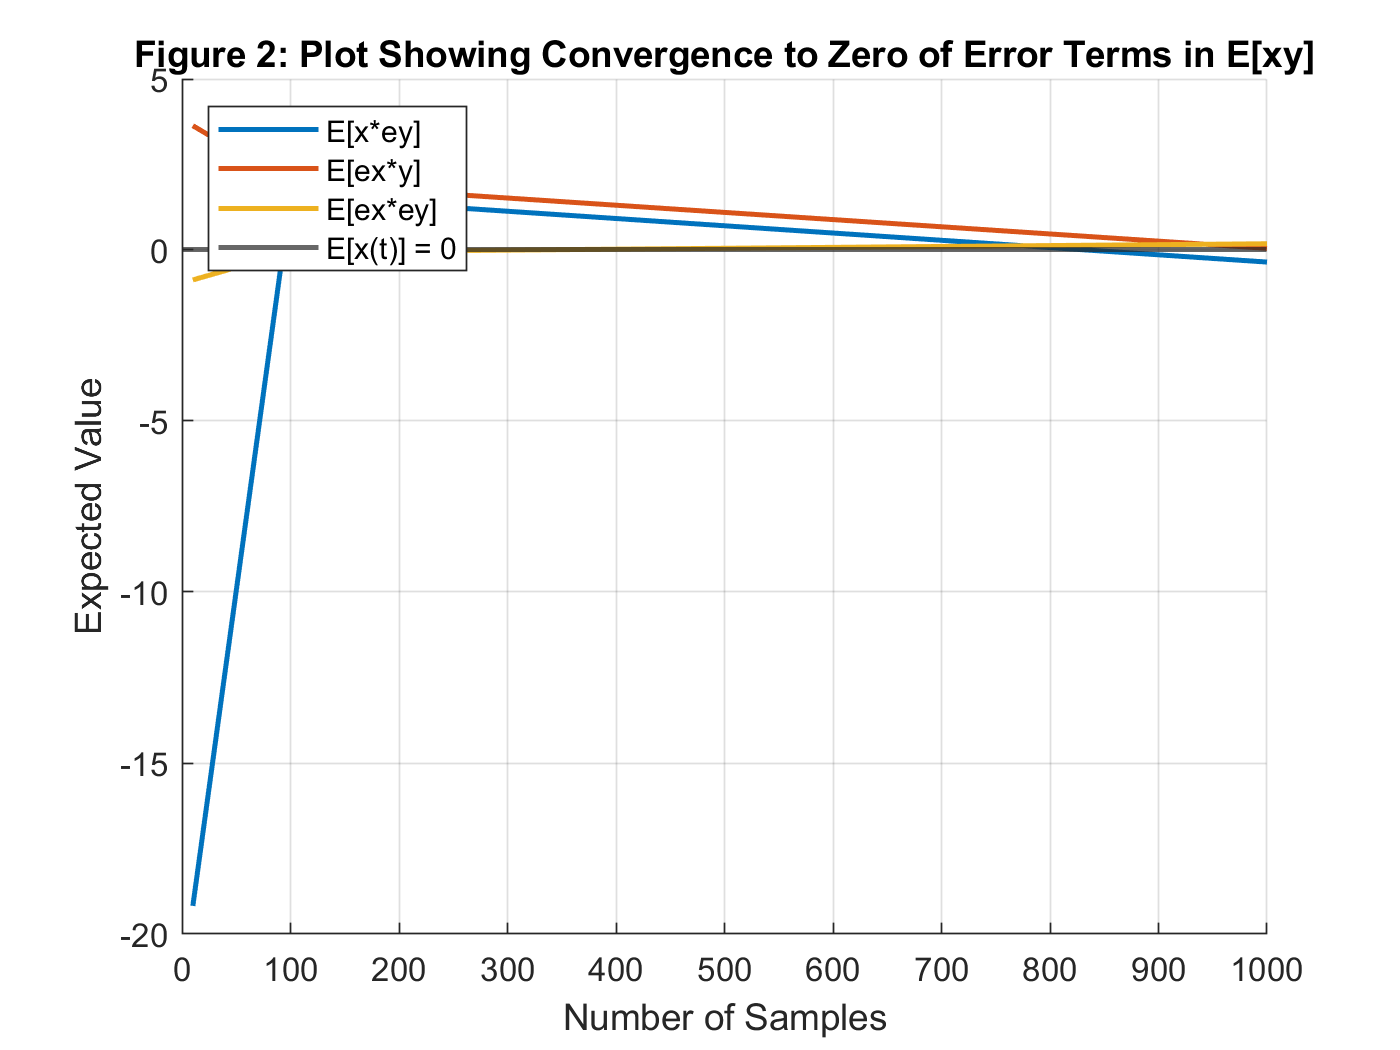

    
% --Plot data to show converging
    figure(3)
    hold on
    plot(N,solutions(2,:),'Linewidth',1.5)
    plot(N,solutions(3,:),'Linewidth',1.5)
    plot(N,solutions(4,:),'Linewidth',1.5)
        yline(0,'Linewidth',1.5)
        grid on
        lgd = legend('E[x*ey]','E[ex*y]','E[ex*ey]','E[x(t)] = 0');
        lgd.Location = 'northwest';
        title('Figure 2: Plot Showing Convergence to Zero of Error Terms in E[xy]')
        xlabel('Number of Samples')
        ylabel('Expected Value')

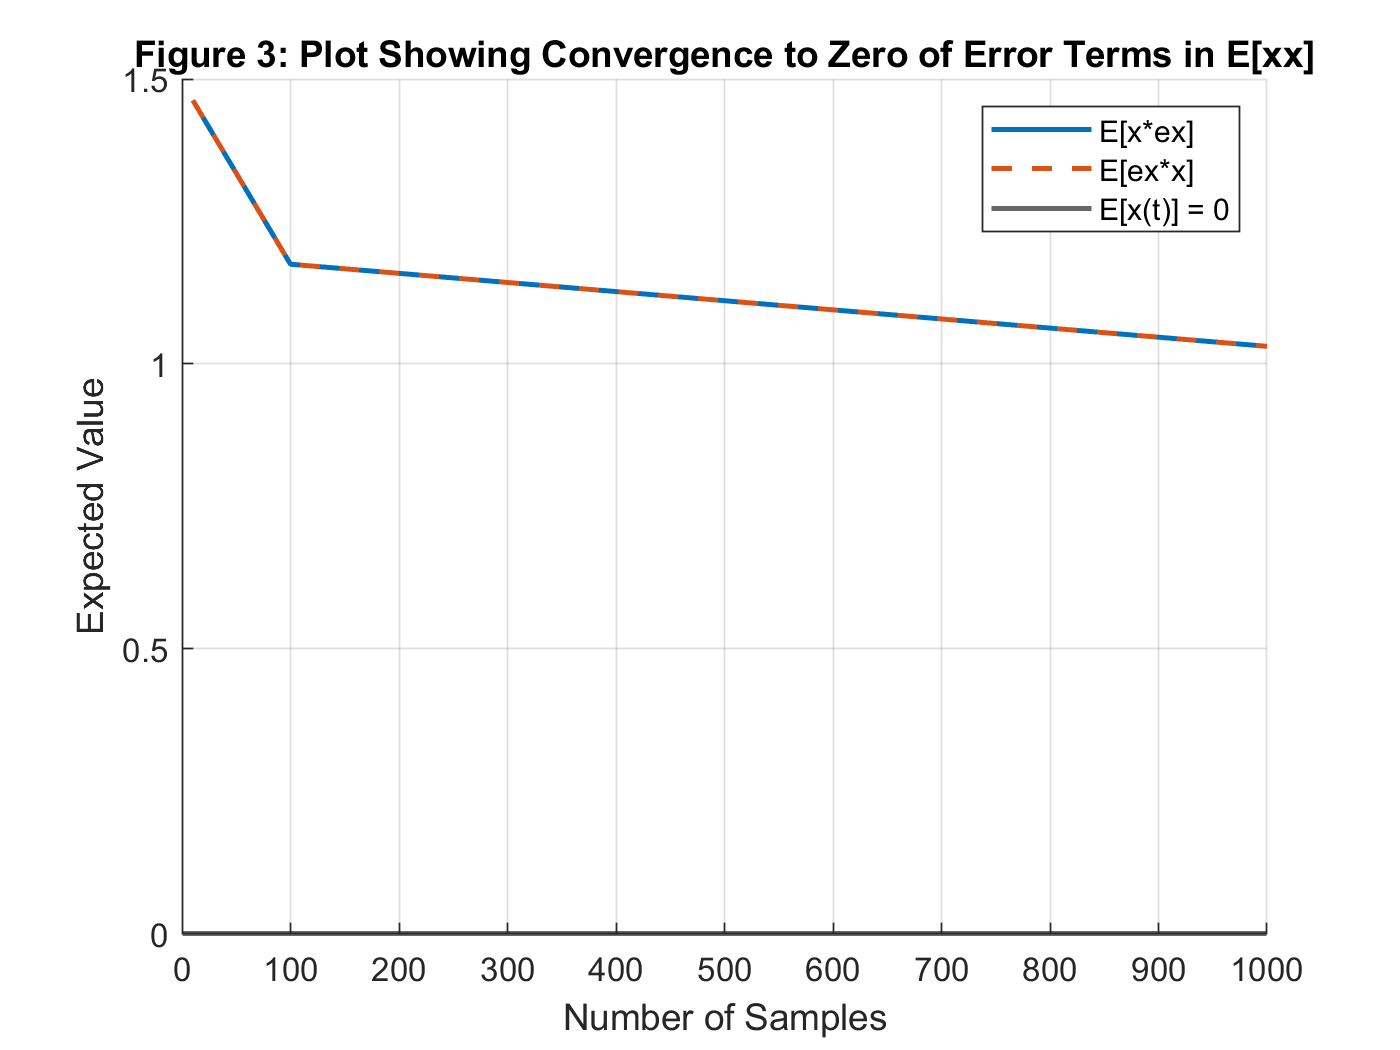

        
% --Plot for E[xx] error terms
    figure(4)
    hold on
    plot(N,solutions(6,:),'Linewidth',1.5)
    plot(N,solutions(7,:),'--','Linewidth',1.5)
        yline(0,'Linewidth',1.5)
        grid on
        lgd = legend('E[x*ex]','E[ex*x]','E[x(t)] = 0');
        lgd.Location = 'northeast';
        title('Figure 3: Plot Showing Convergence to Zero of Error Terms in E[xx]')
        xlabel('Number of Samples')
        ylabel('Expected Value')

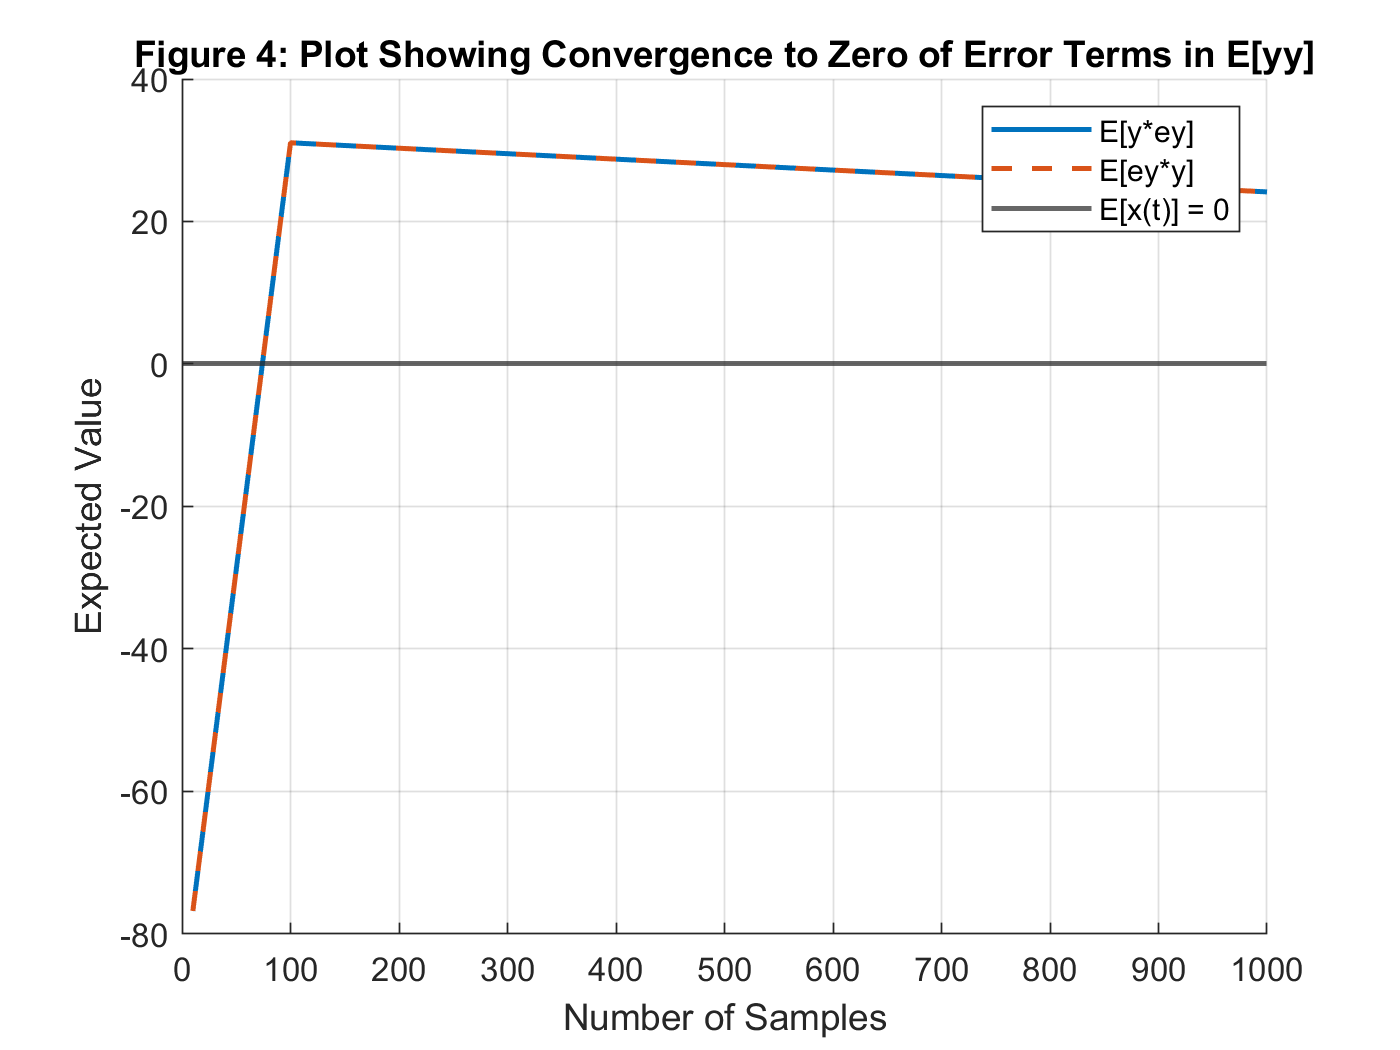

        
% --Plot for E[yy] error terms
    figure(5)
    hold on
    plot(N,solutions(10,:),'Linewidth',1.5)
    plot(N,solutions(11,:),'--','Linewidth',1.5)
        yline(0,'Linewidth',1.5)
        grid on
        lgd = legend('E[y*ey]','E[ey*y]','E[x(t)] = 0');
        lgd.Location = 'northeast';
        title('Figure 4: Plot Showing Convergence to Zero of Error Terms in E[yy]')
        xlabel('Number of Samples')
        ylabel('Expected Value')

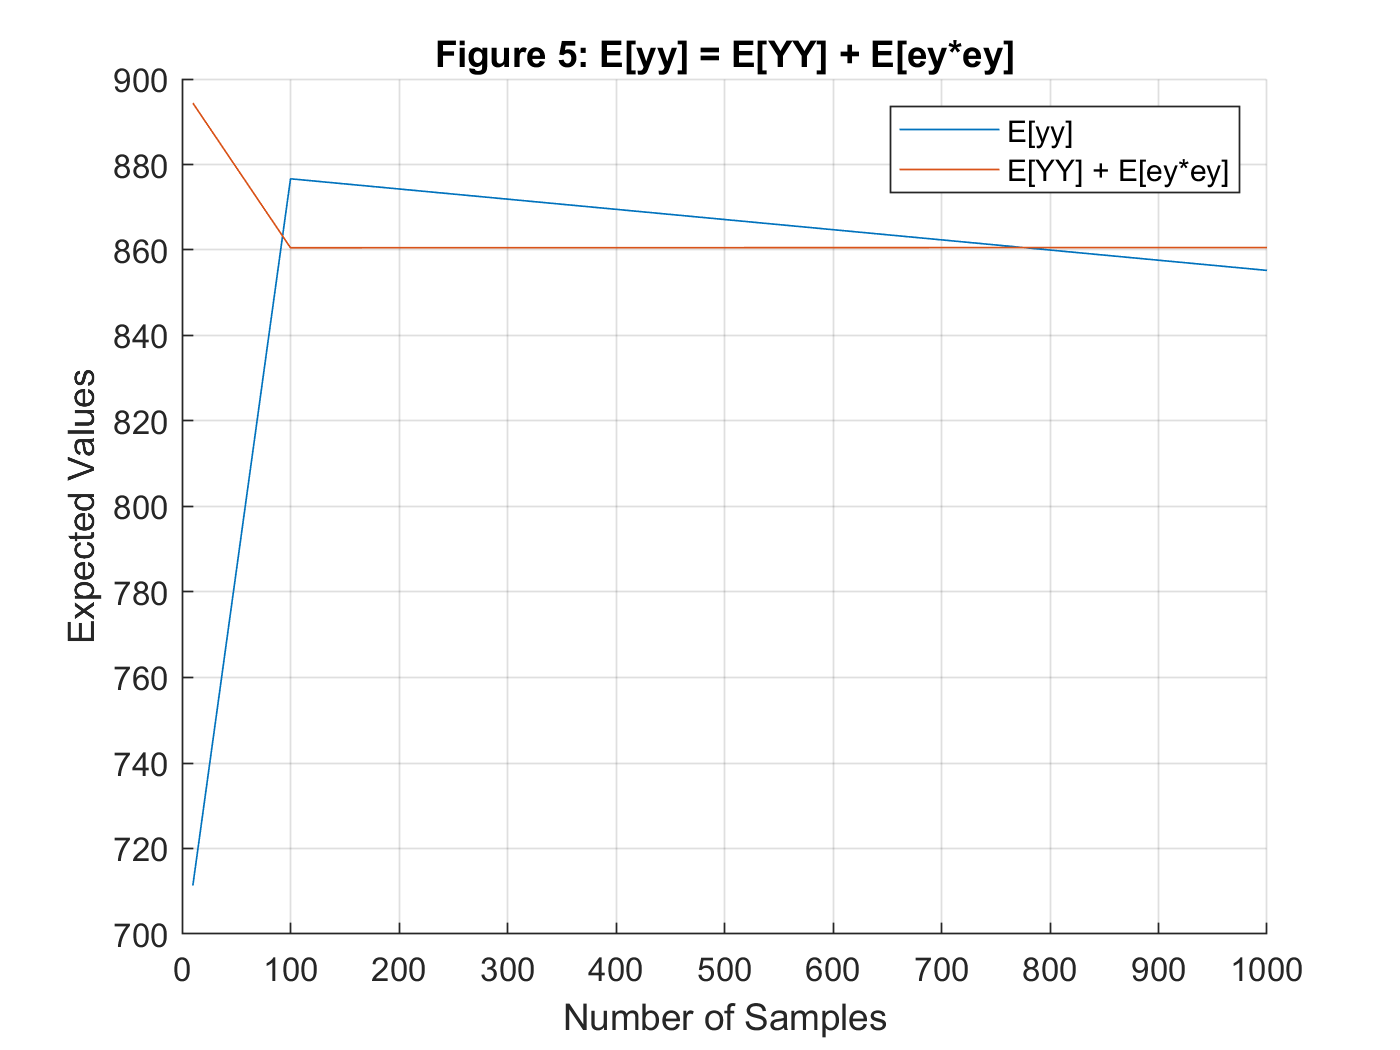

        
% --Plot for sum of E[YY] + E[eyey]
    figure(6)
    hold on
    plot(N,sums(3,:))
    plot(N,sums(4,:))
        title('Figure 5: E[yy] = E[YY] + E[ey*ey]')
        lgd = legend('E[yy]','E[YY] + E[ey*ey]');
        lgd.Location = 'northeast';
        grid on
        xlabel('Number of Samples')
        ylabel('Expected Values')

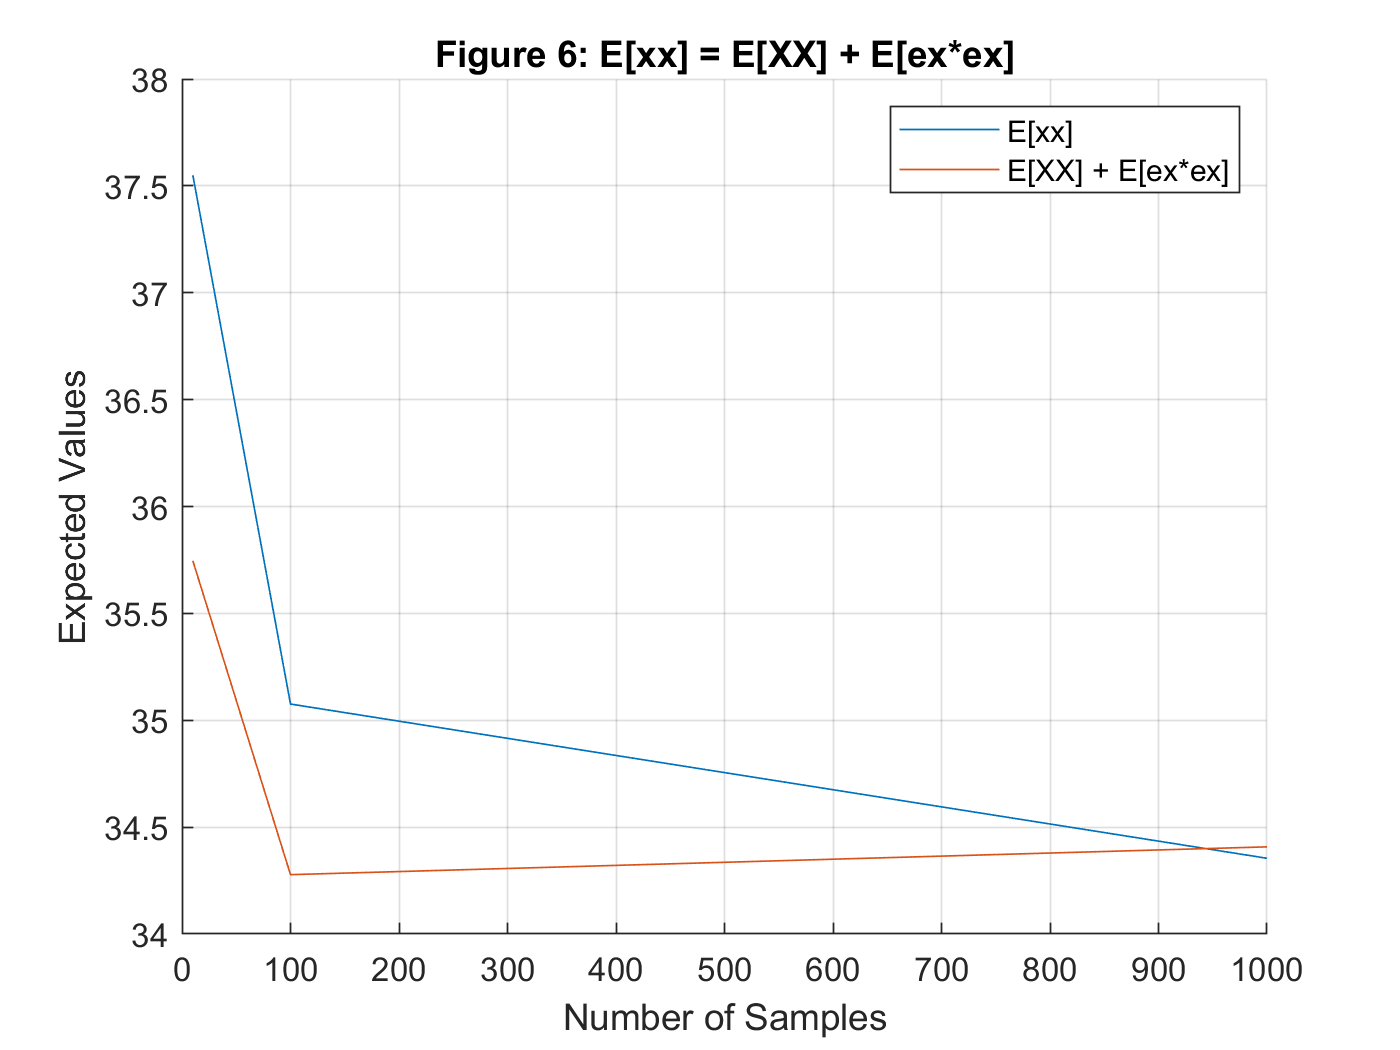

        
% --Plot for sum of E[XX] + E[exex]
    figure(7)
    hold on
    plot(N,sums(1,:))
    plot(N,sums(2,:))
        title('Figure 6: E[xx] = E[XX] + E[ex*ex]')
        lgd = legend('E[xx]','E[XX] + E[ex*ex]');
        lgd.Location = 'northeast';
        grid on
        xlabel('Number of Samples')
        ylabel('Expected Values')

### Analysis of data

    Figure 2 shows the terms that contain error values in the calculation of E[xy]. As we can see, as the number of samples increases to about 1000, the value of these numbers are approaching 0. If we are to take even more samples, the values will all converge to 0. Because of this, we can see if figure 1 that the value of the summation of all the terms will converge to the value of E[xy] just like in class. As a result we can say that the value of E[xy] when the sample size is infinite is going to be equal to xy.

    In figures 3 and 4, the error terms (E[ex*x] and E[x*ex]) were calculated for the 3 different sample sizes. We can see that as the sample sizes get larger, the values of these terms begin to converge to zero as well. This is in line with the theory that was established in class. Both of these terms will be the same because the terms are commutative. In other words ex*x = x*ex, so the expected value will be the same because the data set is the same. 

    In figures 5 and 6, we established that E[xx] = E[XX] + E[ex*ex] and the same is true for E[yy]. We can see that in the beginning with small sample sizes, this does not hold. As the sample sizes get larger, they begin to converge on eachother which is what is established by theory in class.